clear;      % Removes all variables from the workspace
clc;        % Clears the Command Window
close all;  % Closes any hidden or external figure windows

raw_data = load("/Users/djangovanderplas/Documents/University/IntegrationProject/sc_integration_project/system_identification/identification_data/whole_system_identification/prbs_long.mat");

% Define the experiment suffixes (matching your variable names)
experiments = {'PRBS_Long1_Amp0_5', ...
               'PRBS_Long2_Amp0_15', ...
               'PRBS_Long2_Amp0_5', ...
               'PRBS_Long3_Amp0_1'};

for i = 1:length(experiments)
    suffix = experiments{i};
    
    u_data       = raw_data.(sprintf('u_%s', suffix));
    theta_1_data = raw_data.(sprintf('theta_1_%s', suffix));
    theta_2_data = raw_data.(sprintf('theta_2_%s', suffix));
    
    expData(i).t        = u_data.Time;
    expData(i).u        = u_data.Data;
    expData(i).theta_1  = theta_1_data.Data;
    expData(i).theta_2  = theta_2_data.Data;
    expData(i).name     = suffix;
end

expData(strcmp({expData.name}, 'PRBS_Long1_Amp0_5')) = [];
expData(strcmp({expData.name}, 'PRBS_Long2_Amp0_5')) = [];

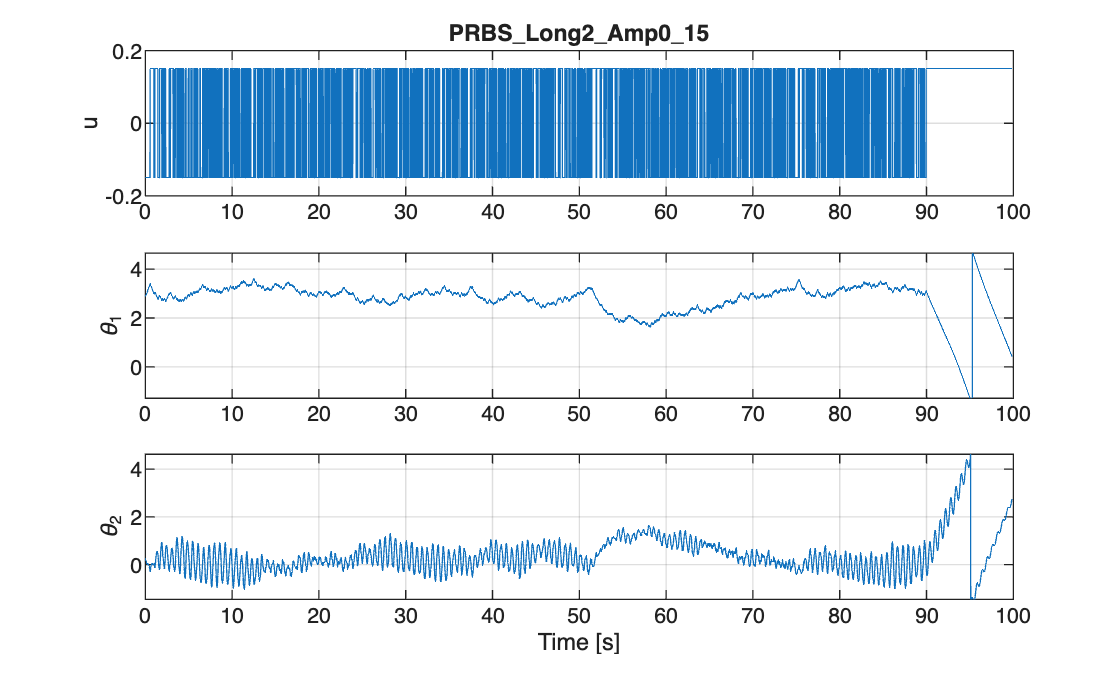

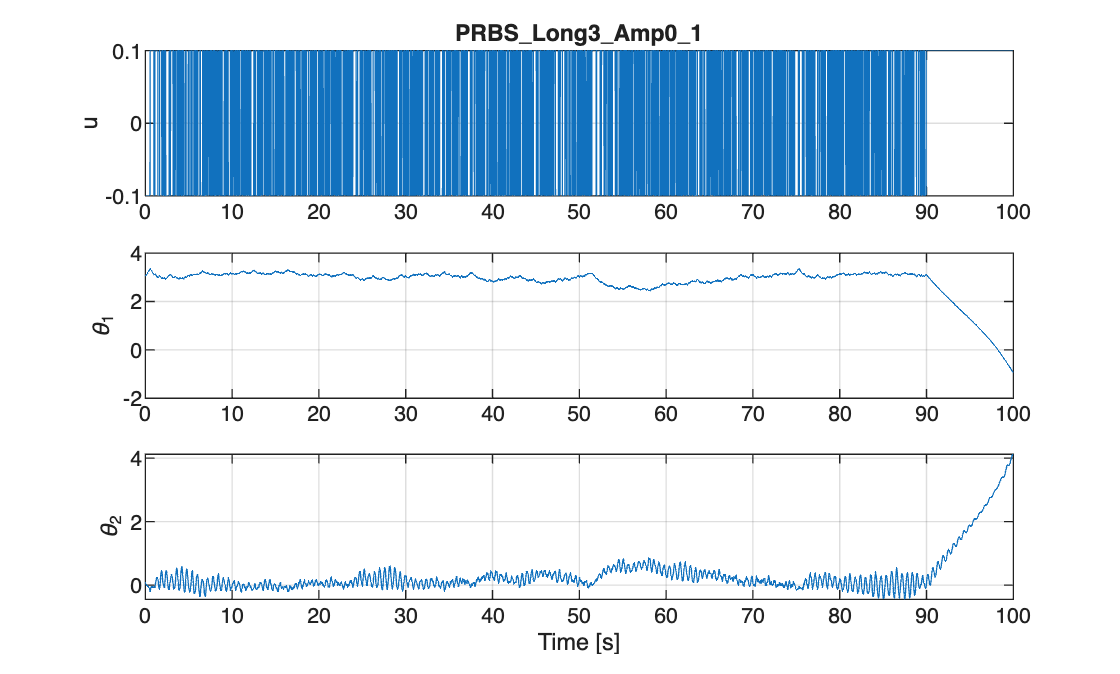

for i = 1:length(expData)
    figure('Name', expData(i).name, 'NumberTitle', 'off');
    
    subplot(3,1,1);
    plot(expData(i).t, expData(i).u);
    ylabel('u');
    title(strrep(expData(i).name, '_', '\_'));  % avoid subscript rendering
    grid on;
    
    subplot(3,1,2);
    plot(expData(i).t, expData(i).theta_1);
    ylabel('\theta_1');
    grid on;
    
    subplot(3,1,3);
    plot(expData(i).t, expData(i).theta_2);
    ylabel('\theta_2');
    xlabel('Time [s]');
    grid on;
end

% Trim and split parameters
t_cut_start = 10;    % seconds to cut from the start
t_cut_end   = 15;    % seconds to cut from the end (relative to signal end)
train_frac  = 0.7;   % fraction of remaining data used for training

for i = 1:length(expData)
    t = expData(i).t;
    
    % Build mask for the usable window
    t_end = t(end) - t_cut_end;
    mask  = (t >= t_cut_start) & (t <= t_end);
    
    % Trim all signals
    t_trim  = t(mask);
    u_trim  = expData(i).u(mask);
    th1_trim = expData(i).theta_1(mask);
    th2_trim = expData(i).theta_2(mask);
    
    % Split index
    N = length(t_trim);
    N_train = floor(train_frac * N);
    
    % Training set
    expData(i).train.t       = t_trim(1:N_train);
    expData(i).train.u       = u_trim(1:N_train);
    expData(i).train.theta_1 = th1_trim(1:N_train);
    expData(i).train.theta_2 = th2_trim(1:N_train);
    
    % Validation set
    expData(i).val.t       = t_trim(N_train+1:end);
    expData(i).val.u       = u_trim(N_train+1:end);
    expData(i).val.theta_1 = th1_trim(N_train+1:end);
    expData(i).val.theta_2 = th2_trim(N_train+1:end);
end

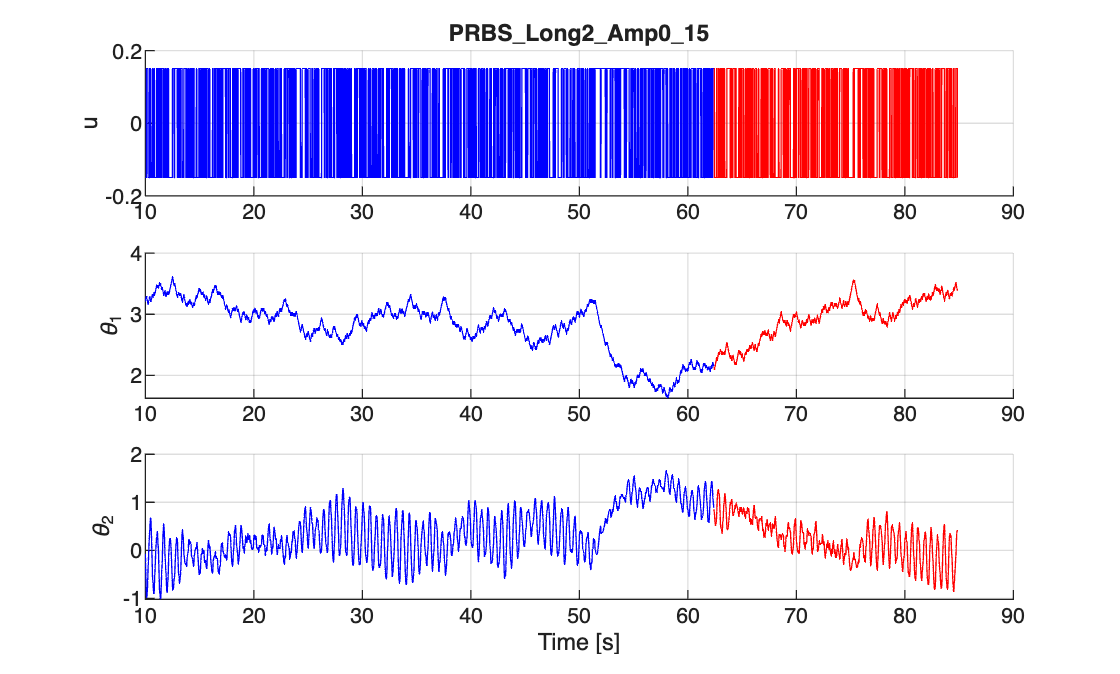

% Select which experiment to plot
idx = 1;   % change this to 1, 2, 3

ed = expData(idx);

figure('Name', ed.name, 'NumberTitle', 'off');

subplot(3,1,1); hold on;
plot(ed.train.t, ed.train.u, 'b');
plot(ed.val.t,   ed.val.u,   'r');
ylabel('u'); grid on;
title(strrep(ed.name, '_', '\_'));
% legend('train', 'val', 'Location', 'best');

subplot(3,1,2); hold on;
plot(ed.train.t, ed.train.theta_1, 'b');
plot(ed.val.t,   ed.val.theta_1,   'r');
ylabel('\theta_1'); grid on;

subplot(3,1,3); hold on;
plot(ed.train.t, ed.train.theta_2, 'b');
plot(ed.val.t,   ed.val.theta_2,   'r');
ylabel('\theta_2'); xlabel('Time [s]'); grid on;